# run_comparison.m

Compare a basic SEIR model with a demographic SEIR model on DRC 2026 Ebola case data, using nonlinear least squares (lsqnonlin) and leave-future-out cross-validation.

Files needed in the top-level repo folder (run from there): load_cases.m - loads the data and applies the frozen cutoff date simulate_cum.m - SEIR model, returns cumulative cases fit_model.m - nonlinear least squares fit with several starting points data/insp_sitrep__national_cumulative_confirmed_cases__daily.csv

Data source: INRB-UMIE/BDBV2026-Data (GitHub), tag build-2026-10-01-b077a6c. Only real report dates are used: nothing interpolated enters the fit or the scoring.

clear; clc; close all;

## 1. SETTINGS ------------------------------------------------------

Model assumptions (fixed, not fitted)

N      = 7e6;        % TODO: replace with a cited at-risk population
sigma  = 1/9.4;      % TODO: cite source (1 / incubation period, per day)
gamma  = 1/8;        % TODO: cite source (1 / infectious period, per day)
mu_dem = 1/(60*365); % birth/death rate for the demographic model (per day)

models(1).name = 'Basic SEIR';        models(1).mu = 0;
models(2).name = 'Demographic SEIR';  models(2).mu = mu_dem;

% Fitting
n_starts = 10;       % random starting points per fit

% Leave-future-out cross-validation
first_origin = 40;   % first training window uses reports 1..40
origin_step  = 5;    % move the forecast origin forward 5 reports each time
h            = 5;    % forecast the next 5 reporting intervals (~1 week)

rng(1);              % reproducible random starting points

## 2. LOAD DATA -----------------------------------------------------

(data file and cutoff date are set in load_cases.m)

[report_date, cum_obs] = load_cases();

Data: 101 reports from 2026-05-14 to 2026-09-21 (cutoff 2026-09-21; last date in file 2026-09-29)



t           = days(report_date - report_date(1));   % t(1) = 0
n           = numel(t);
dt          = diff(t);                  % length of each reporting interval
obs_per_day = diff(cum_obs) ./ dt;      % observed average cases per day

nm = numel(models);

## 3. IN-SAMPLE FIT (all data up to the cutoff) --------------------

theta_full  = zeros(nm, 3);
fit_per_day = cell(1, nm);
rmse_in     = zeros(1, nm);

for m = 1:nm
    theta_full(m, :) = fit_model(t, cum_obs, N, models(m).mu, sigma, gamma, n_starts);
    C = simulate_cum(theta_full(m, :), t, N, models(m).mu, sigma, gamma);
    fit_per_day{m} = diff(C) ./ dt;
    rmse_in(m) = sqrt(mean((fit_per_day{m} - obs_per_day).^2));
    fprintf('Finished in-sample fit for %s\n', models(m).name);
end

Finished in-sample fit for Basic SEIR
Finished in-sample fit for Demographic SEIR


## 4. LEAVE-FUTURE-OUT CROSS-VALIDATION ----------------------------

For each forecast origin c: fit on reports 1..c, forecast reports c+1..c+h, and score on those held-out reporting intervals (cases/day).

origins = first_origin:origin_step:(n - h);
if isempty(origins)
    error('Not enough data for these CV settings. Reduce first_origin or h.');
end

mae  = nan(numel(origins), nm);
rmse = nan(numel(origins), nm);

for m = 1:nm
    for k = 1:numel(origins)
        c  = origins(k);
        th = fit_model(t(1:c), cum_obs(1:c), N, models(m).mu, sigma, gamma, n_starts);

        % simulate through the forecast window, then difference
        C = simulate_cum(th, t(1:c+h), N, models(m).mu, sigma, gamma);
        pred_per_day = diff(C(c:c+h))       ./ diff(t(c:c+h));
        true_per_day = diff(cum_obs(c:c+h)) ./ diff(t(c:c+h));

        err = pred_per_day - true_per_day;
        mae(k, m)  = mean(abs(err));
        rmse(k, m) = sqrt(mean(err.^2));
    end
    fprintf('Finished CV for %s\n', models(m).name);
end

Finished CV for Basic SEIR
Finished CV for Demographic SEIR


## 5. RESULTS TABLES ------------------------------------------------

results = table({models.name}', rmse_in', ...
    mean(mae, 'omitnan')', mean(rmse, 'omitnan')', ...
    'VariableNames', {'Model', 'InSample_RMSE', 'CV_MAE', 'CV_RMSE'});
disp(results);

           Model            InSample_RMSE    CV_MAE    CV_RMSE
    ____________________    _____________    ______    _______

    {'Basic SEIR'      }       26.464        29.015     33.24 
    {'Demographic SEIR'}       26.464        29.016    33.241 




params = array2table(theta_full, 'VariableNames', {'beta', 'E0', 'I0'}, ...
    'RowNames', {models.name});
disp(params);

                         beta          E0          I0  
                        _______    __________    ______

    Basic SEIR          0.14692    7.4654e-08     464.6
    Demographic SEIR    0.14703    7.2597e-08    464.41




fprintf('\nSettings: N = %g, sigma = %.4f, gamma = %.4f, mu (demographic) = %.3g\n', ...
    N, sigma, gamma, mu_dem);


Settings: N = 7e+06, sigma = 0.1064, gamma = 0.1250, mu (demographic) = 4.57e-05


fprintf('Data: %d reports, %s to %s\n', n, ...
    char(report_date(1), 'yyyy-MM-dd'), char(report_date(end), 'yyyy-MM-dd'));

Data: 101 reports, 2026-05-14 to 2026-09-21


fprintf('CV: %d forecast origins, horizon = %d reports\n', numel(origins), h);

CV: 12 forecast origins, horizon = 5 reports


## 6. PLOTS ---------------------------------------------------------

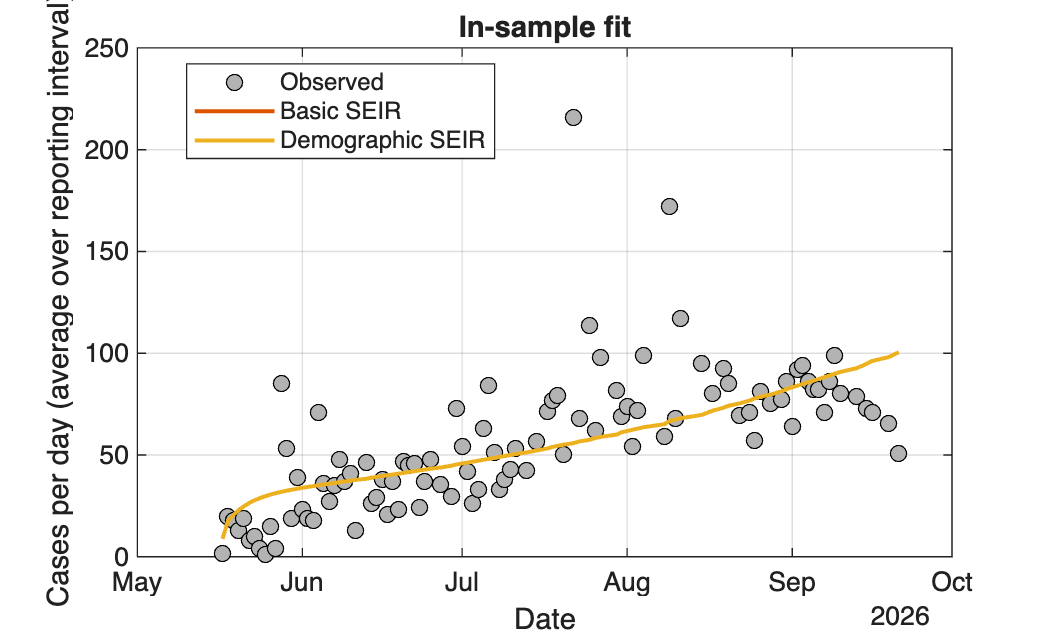

fig1 = figure('Color', 'w');
plot(report_date(2:end), obs_per_day, 'ko', 'MarkerFaceColor', [0.7 0.7 0.7]);
hold on;
for m = 1:nm
    plot(report_date(2:end), fit_per_day{m}, '-', 'LineWidth', 1.5);
end
xlabel('Date');
ylabel('Cases per day (average over reporting interval)');
legend([{'Observed'}, {models.name}], 'Location', 'best');
title('In-sample fit'); grid on;

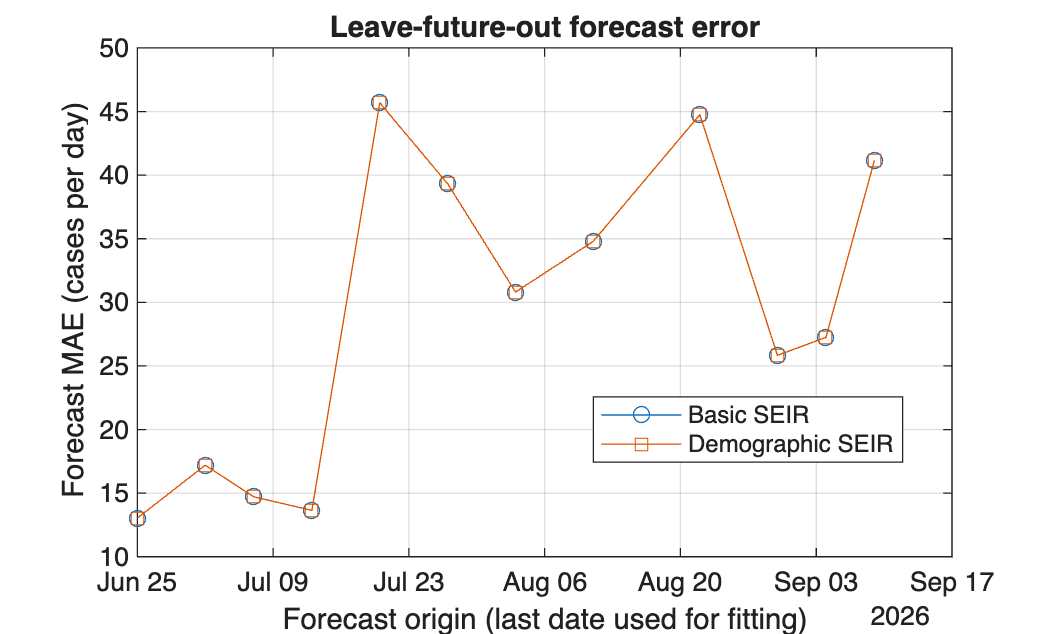


fig2 = figure('Color', 'w');
plot(report_date(origins), mae(:, 1), '-o'); hold on;
plot(report_date(origins), mae(:, 2), '-s');
xlabel('Forecast origin (last date used for fitting)');
ylabel('Forecast MAE (cases per day)');
legend({models.name}, 'Location', 'best');
title('Leave-future-out forecast error'); grid on;

## 7. SAVE RESULTS FOR THE WRITE-UP --------------------------------

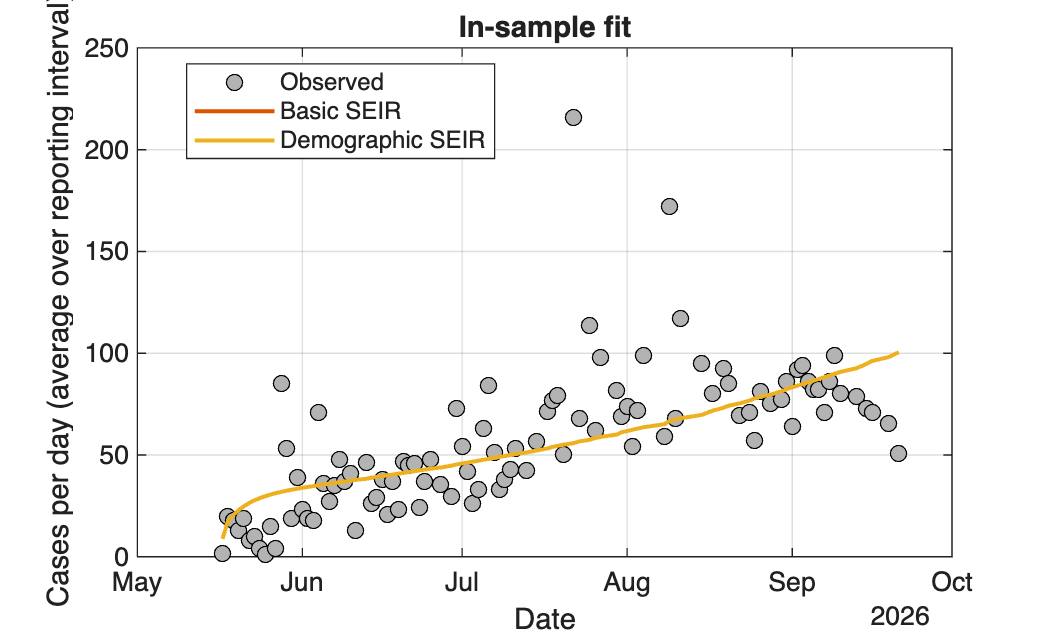

if ~isfolder('results'), mkdir('results'); end
writetable(results, fullfile('results', 'model_comparison_summary.csv'));
writetable(params,  fullfile('results', 'fitted_parameters.csv'), 'WriteRowNames', true);
saveas(fig1, fullfile('results', 'insample_fit.png'));

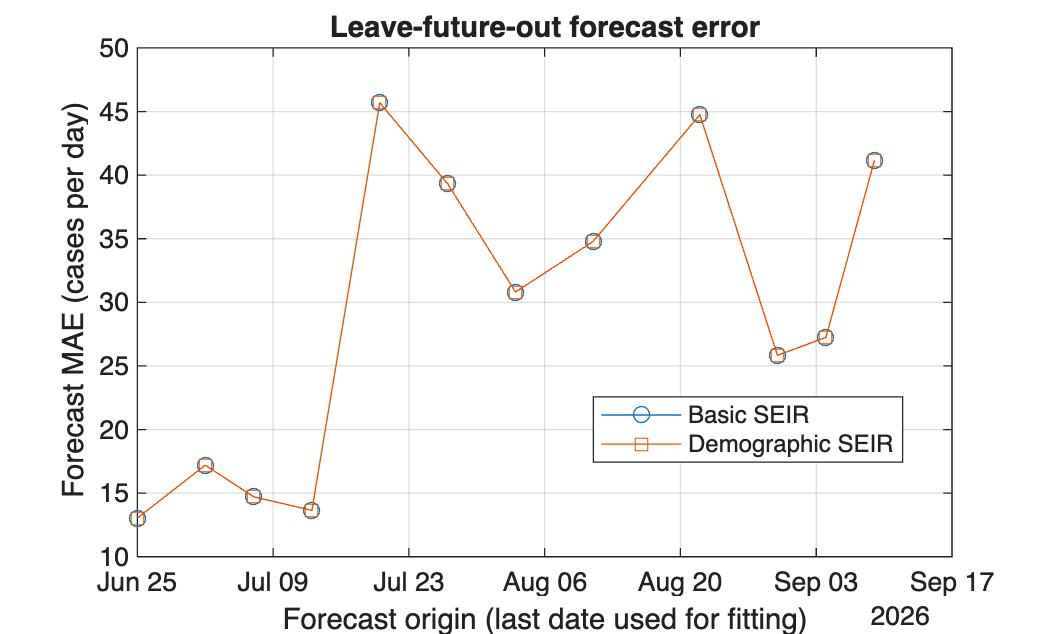

saveas(fig2, fullfile('results', 'cv_forecast_error.png'));